# MATLAB Code for ELE466 Group 1's Modelling Assignment


% Written by: Erick Stanzah
% Finished on: 1/11/2025

% Clear Command Window and Workspace
clear,clc 



## MODEL PARAMETERS


% These are the default (control) parameter values used in testing
init_wheel = 0.2;   % Initial position of wheel
init_chassis = 0.4; % Initial position of chassis
init_seat = 0.6;    % Initial position of seat
m1 = 40;            % Weight of wheel
m2 = 300;           % Weight of chassis
m3 = 75;            % Weight of seat
k1 = 2500;          % Spring constant between seat and chassis
k2 = 15000;         % Spring constant between chassis and wheel
k3 = 180000;        % Spring constant between wheel and ground
c1 = 80;            % Damping constant between seat and chassis
c2 = 1200;          % Damping constant between chassis and wheel
c3 = 40;            % Damping constant between seat and chassis
c4 = 0;             % Damping constant between wheel and ground



## STATE SPACE MATRIX


% This section contains the Matrices needed for State Space Matrix and its system output
% A Matrix
A = [-c2/m1 c2/m1 0 -(k2+k3)/m1 k2/m1 0;
    c2/m2 -(c1+c2+c3)/m2 (c1+c3)/m2 k2/m2 -(k1+k2)/m2 k1/m2;
    0 (c1+c3)/m3 -(c1+c3)/m3 0 k1/m3 -k1/m3;
    1 0 0 0 0 0; 0 1 0 0 0 0; 0 0 1 0 0 0];

% B Matrix
B = [k3/m1;0;0;0;0;0];

% C Matrix
C = [1 0 0 0 0 0;
    0 1 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 1 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1];

% D Matrix
D = [0;0;0;0;0;0];

% Transfer Function from the State Space Matrix
[n,d] = ss2tf(A,B,C,D);



## INPUT AND DISTURBANCES


% This section contains the 3 ground inputs used for the model simulation
% Parameters for upwards slope
v = 10;       % velocity of the model
h = 0.3;      % height of the ramp
steep = 15;   % steepness of the ramp
t_stop = 10;  % simulation end time

ramp = 0:0.02:1;                % step size of the data points for ramp
time = [0;1;1+steep*ramp'/v;5]; % time profile
ground = [0;0;ramp'*h;h];       % ground profile
profile = [time,ground];        % slope input to the model

% Parameters for wavy road
amplitude = 0.2;                % amplitude of the wavy road
wavy_t = 0:pi/25:6*pi;          % time profile of wavy road
wavy_h = amplitude*sin(wavy_t); % ground profile of wavy road
profile_w = [wavy_t', wavy_h']; % wavy road input to the model

% Parameters for road bump
drop = 1:-0.02:0;       % step size of the data points for road bump's downward slope
drop_t = 1+steep/v;     % time when the slope starts going downwards
bump = 0.1;             % height of the bump
time_b = [0;1;1+steep*ramp'/v;drop_t+steep*ramp'/v;5]; % time profile of road bump
ground_b = [0;0;ramp'*bump;drop'*bump;0];    % ground profile of road bump
profile_b = [time_b, ground_b];              % road bump input to the model



## SIMULATION


% Commands to run the Simulink models
% (change the ground inputs manually in the Simulink files)
% Simulation for Simulink model based on EOM
sim("Lab_model_EOM.slx");

% Simulation for Simulink model based on Transfer Function from Laplace
sim("Lab_model_laplace.slx");

% Simulation for Simulink model based on State Space Matrix
sim("Lab_model_ss2tf.slx");



## PLOTTING

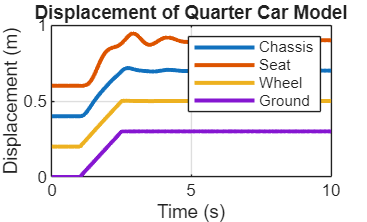


% This section is to plot the results and use it to tune the model
% Graphs for the EOM Simulink Model
% Graph for the displacements of the model
figure(1) 
plot(displacement.time,displacement.signals.values,'LineWidth',2)
grid
legend('Chassis','Seat','Wheel','Ground')
title('Displacement of Quarter Car Model')
ylabel('Displacement (m)')
xlabel('Time (s)')

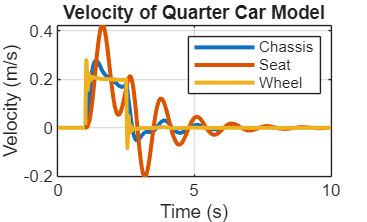


% Graph for the velocities of the model
figure(2) 
plot(velocity.time,velocity.signals.values,'LineWidth',2)
grid
legend('Chassis','Seat','Wheel')
title('Velocity of Quarter Car Model')
ylabel('Velocity (m/s)')
xlabel('Time (s)')

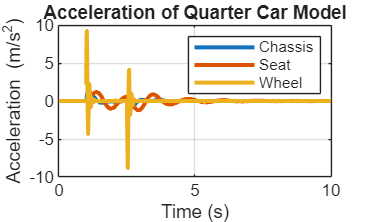


% Graph for the accelerations of the model
figure(3) 
plot(acceleration.time,acceleration.signals.values,'LineWidth',2)
grid
legend('Chassis','Seat','Wheel')
title('Acceleration of Quarter Car Model')
ylabel('Acceleration (m/s^{2})')
xlabel('Time (s)')

## VALIDATION WITH DIFFERENT MODELS (ONLY DISPLACEMENT AND VELOCITY)

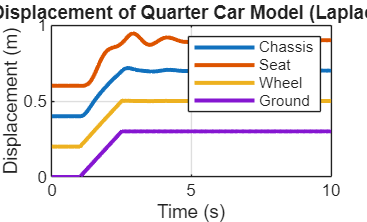


% This section is to check the results with the graphs from the EOM model
% Graphs for the Transfer Function from Laplace Simulink Model
% Graphs for the displacement of the model
figure(4) 
plot(lap_disp.time,lap_disp.signals.values,'LineWidth',2)
grid
legend('Chassis','Seat','Wheel','Ground')
title('Displacement of Quarter Car Model (Laplace)')
ylabel('Displacement (m)')
xlabel('Time (s)')

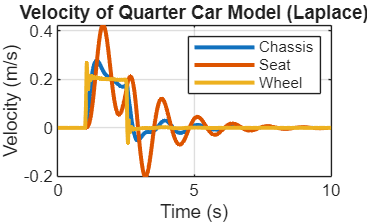


% Graph for the velocities of the model
figure(5) 
plot(lap_velo.time,lap_velo.signals.values,'LineWidth',2)
grid
legend('Chassis','Seat','Wheel')
title('Velocity of Quarter Car Model (Laplace)')
ylabel('Velocity (m/s)')
xlabel('Time (s)')

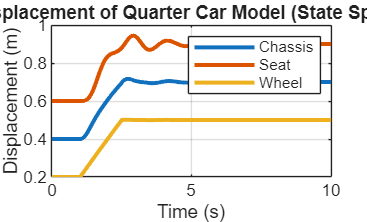



% Graphs for the State Space Simulink Models
% Graphs for the displacement of the model
figure(6)
% Manually add the initial position to wheel, chassis, and seat
plot(ModelData.time,ModelData.signals.values(:,5)+init_chassis,'LineWidth',2)
hold on   % Rearranging the order the data is plotted for same line colors as previous graphs
plot(ModelData.time,ModelData.signals.values(:,6)+init_seat,'LineWidth',2)
hold on
plot(ModelData.time,ModelData.signals.values(:,4)+init_wheel,'LineWidth',2)
hold off
grid
legend('Chassis','Seat','Wheel')
title('Displacement of Quarter Car Model (State Space)')
ylabel('Displacement (m)')
xlabel('Time (s)')

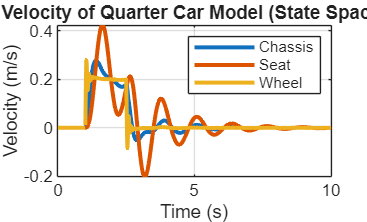


% Graph for the velocities of the model
figure(7)
plot(ModelData.time,ModelData.signals.values(:,2:3),'LineWidth',2)
hold on   % Rearranging the order the data is plotted for same line colors as previous graphs
plot(ModelData.time,ModelData.signals.values(:,1),'LineWidth',2)
hold off 
grid
legend('Chassis','Seat','Wheel')
title('Velocity of Quarter Car Model (State Space)')
ylabel('Velocity (m/s)')
xlabel('Time (s)')